# Gabriel Colangelo

clear
close all
clc

% Earth Parameters
mu_earth        = 398600.4415;
R_earth         = 6378.1363;

% OTV Parameters - Circular Orbit
a_otv           = 1.5*R_earth;
e_otv           = 0;
i_otv           = 0;
theta_D         = 0;

% Space Station Parameters
a_ss            = 8*R_earth;
e_ss            = 0.2;
i_ss            = 30;
RAAN_ss         = 45;
AOP_ss          = 60;
theta_A         = 240;

## Problem 2a)

Find: a, type, e, p, e, $v_D$, $\gamma_D$, $\theta^*_D$, $v_A$, $\gamma_A$, $\theta^*_A$,$|\Delta \bar{v}_D|, \alpha_D, |\Delta \bar{v}_A|, \alpha_A$

Assume: TOF = 8 hours, Type 1 transfer, mass of space station and OTV negligble. Transfer from OTV to Space Station

% Desired time of flight
TOF_A           = 8*3600;

% Orbit radius at space station arrival
r_ss            = (a_ss*(1 - e_ss^2))/(1 + e_ss*cosd(theta_A - AOP_ss));

% Direction cosine matrix from rotating frame to inertial frame
DCM_ss          =  I_DCM_R(i_ss,theta_A,RAAN_ss);

% Calculate position vectors in inertial frame
r_ss_I          = DCM_ss*[r_ss;0;0];
r_otv_I         = [a_otv;0;0];

% Calculate transfer angle (angle between position vectors)
TA              = acosd(dot(r_ss_I,r_otv_I)/(r_ss*a_otv));

% Solve Lamberts problem
probA           = LambertsProblem(TOF_A, a_otv, r_ss, TA, mu_earth);
fprintf('The semi major axis of the transfer orbit is %.2f km',probA.a)

The semi major axis of the transfer orbit is 32773.37 km


$$r_{ss} = \frac{a(1-e^2)}{1 + e\cos{(\theta - \omega)}} = 61230 \ [km] \\
[IR] =  \pmatrix{C_{\Omega} C_{\theta} - S_{\Omega} C_i S_{\theta}& -C_{\Omega} S_{\theta} - S_{\Omega} C_i C_{\theta}&
              S_{\Omega} S_i\cr S_{\Omega} C_{\theta} + C_{\Omega} C_i S_{\theta}& -S_{\Omega} S_{\theta} + C_{\theta} C_i C_{\Omega}&
              -C_{\Omega} S_i \cr S_i S_{\theta}& S_i C_{\theta}& C_i}  \\
[\bar{r}_{ss}]^I = [IR] [\bar{r}_{ss}]^R  = 10824 \ \hat{x} - 54120 \ \hat{y} - 26513 \ \hat{z} \ [km] \\
[\bar{r}_{OTV}]^I  = 9567 \ \hat{x} \ [km] \\
\cos{\phi} = \frac{\bar{r}_{OTV} \cdot \bar{r}_{ss}}{|\bar{r}_{OTV}||\bar{r}_{ss}|}\\
\text{Type 1: } TA = \phi = 79.82 \ [deg] \\
\\
\text{Law of cosines from space triangle: } \ c^2 = r_{ss}^2 + r_{OTV}^2 - 2r_{ss}r_{OTV}\cos{\phi} \\
\text{Semi-perimeter: } \ s = (r_{ss} + r_{OTV} + c)/2\\
\text{Minimum energy semi major axis} \ a_{min} =  s/2 = 32769 \ [km] \\
\beta_{min} = 2\sin^{-1}{\sqrt{\frac{s-c}{2a_{min}}} = 32.92 \ [deg]\\
TOF_{min} = \sqrt{\frac{a^3}{\mu}}[(\pi - \beta_{min} ) - (\sin{\pi} - \sin{\beta_{min}})] = 8.12 \ [hour]
\\

$$


**The minimum energy time of flight is greater than the desired time of flight, therefore the transfer type is an A. The transfer type is ****1A.**

For a type 1A, the true $\alpha$ and $\beta$ values are related to their principal values through:


$$\alpha = \alpha_0\\
\beta = \beta_0$$


Lamberts problem is solved numerically for $a$ using a bisection method:


$$\beta_0= 2\sin^{-1}{\sqrt{\frac{s-c}{2a}} \\
\alpha_0= 2\sin^{-1}{\sqrt{\frac{s}{2a}} \\
TOF = \sqrt{\frac{a^3}{\mu}}[(\alpha - \beta ) - (\sin{\alpha} - \sin{\beta})] = 8\ [hour] \\
\\
\underline{\mathbf{a = 32773.36 \ [km]}}$$


% Calculate semi latus rectum
p_type1     = max((4*probA.a*(probA.s - a_otv)*(probA.s - r_ss)/probA.c^2)*...
              [sin((probA.alpha + probA.beta)/2)^2, sin((probA.alpha - probA.beta)/2)^2]);
fprintf('The semi latus rectum of the transfer ellipse is %.3f km', p_type1)

The semi latus rectum of the transfer ellipse is 8054.629 km


$$\alpha  = 178.68 \ [deg] \\
\beta = 32.91 \ [deg] \\
p = a(1 - e^2) = \frac{4a(s-r_{ss})(s-r_{OTV})}{c^2}\sin^2{(\frac{\alpha \pm \beta}{2})} = 8054.63 \ \text{or} \ 7946.20 \ [km]\\
\bar{OF} = 2ae$$


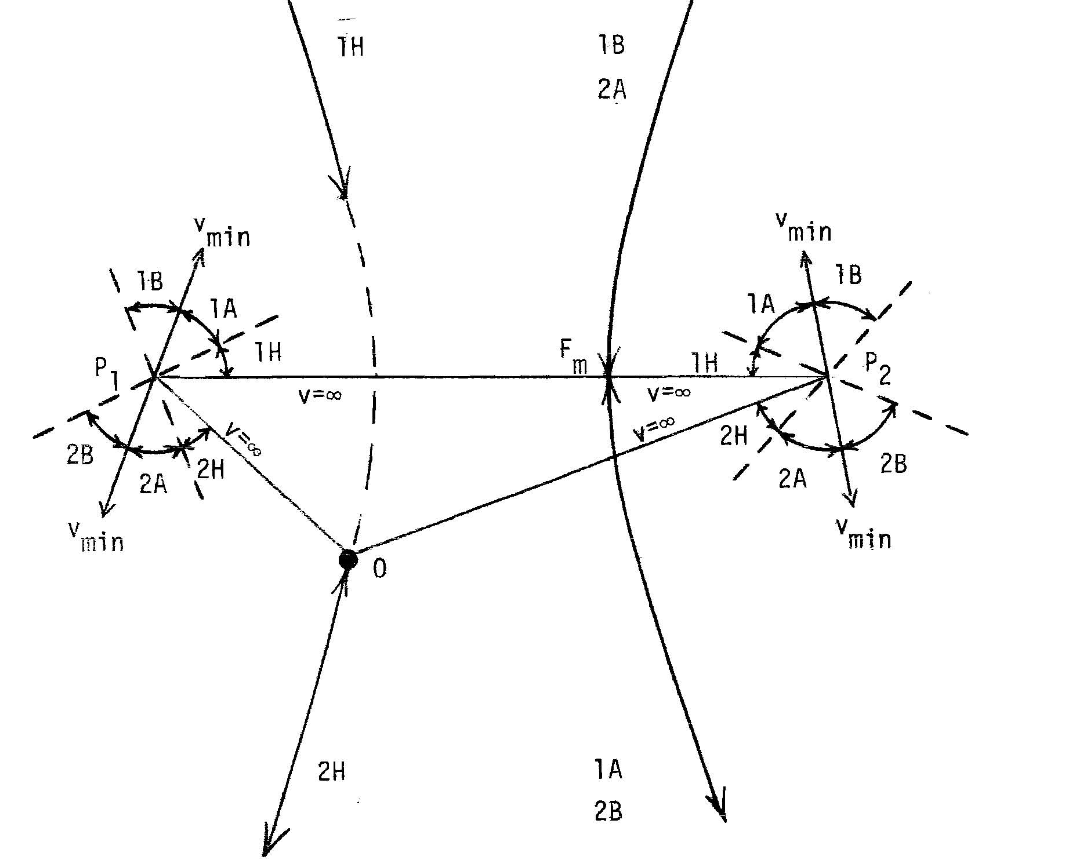

For 1A transfer type, a smaller e is needed as observed in the solution space diagram above. A smaller e will cause an increase in semi-latus rectum. Therefore, the necessary semi-latus rectum value is the larger option.


$$\underline{\mathbf{p = 8054.63 \ [km]}}$$


% Calculate eccentricity
e_type1     = sqrt(1 - p_type1/probA.a);
fprintf('The transfer eccentricity is %.4f ',e_type1)

The transfer eccentricity is 0.8685 


$$e = \sqrt{1 - \frac{p}{a}} \\
\\
\mathbf{e = 0.8685}$$


% Calculate energy of transfer ellipse
energy_type1   = -mu_earth/(2*probA.a);

% Velocity magnitude at departure
v_D            = sqrt(2*(energy_type1 + mu_earth/a_otv));
fprintf('The velocity at departure on the transfer ellipse is %.3f km/s',v_D)

The velocity at departure on the transfer ellipse is 8.436 km/s


$$r_D = r_{OTV}\\
r_A = r_{ss}\\

v_D = \sqrt{2(\frac{\mu}{r_D} - \frac{\mu}{2 a})}\\
v_D = 8.436 \ [km/s]$$


% Calculate true anomaly at departure
true_anomaly_D  = acosd((p_type1/a_otv - 1)/e_type1);

% Calculate true anomaly at arrival
true_anomaly_A  = -acosd((p_type1/r_ss - 1)/e_type1);


$$\theta^* = \cos^{-1}{(\frac{1}{e_m}(\frac{p}{r} - 1))} \\
\theta^*_D = \pm 100.49 \ [deg] \\
\theta^*_A = \pm 179.69 \ [deg] \\
\text{4 possible combinations of $\theta^*_A$ and $\theta^*_D$. However, only one pair produces a transfer angle of 79.82 deg.}\\
\text{Therefore, the pair of true anomaly's must be:} \\
\\
\mathbf{\theta^*_D = 100.49 \ [deg]}\\
\mathbf{\theta^*_A = -179.69 \ [deg]  = 180.31 \ [deg]}\\$$


% Minimum energy transfer specific angular momentum
h_type1         = sqrt(mu_earth*p_type1);

% Flight path angle at departure
gamma_D         = sign(true_anomaly_D)*acosd(h_type1/(a_otv*v_D));
fprintf('The flight path angle at departure is %.3f deg',gamma_D)

The flight path angle at departure is 45.407 deg


$$h = \sqrt{\mu p}\\
h = r_Dv_D\cos{\gamma_D}\\
\\
\gamma_D = 45.41 \ [deg] \ \ \text{Ascending based on $\theta^*_D$, so $\gamma$ > 0}$$


% Velocity magnitude at arrival
v_A            = sqrt(2*(energy_type1 + mu_earth/r_ss));
fprintf('The velocity at arrival on the transfer ellipse is %.3f km/s',v_A)

The velocity at arrival on the transfer ellipse is 0.926 km/s


$$v_A = \sqrt{2(\frac{\mu}{r_A} - \frac{\mu}{2 a})}\\
v_A = 0.926 \ [km/s]$$


% Flight path angle at arrival
gamma_A        = sign(true_anomaly_A)*acosd(h_type1/(r_ss*v_A));
fprintf('The flight path angle at arrival is %.3f deg',gamma_A)

The flight path angle at arrival is -2.025 deg


$$h = \sqrt{\mu p}\\
h = r_Av_A\cos{\gamma_A}\\
\\
\gamma_A = -2.025 \ [deg] \ \ \text{Descending based on $\theta^*_A$, so $\gamma$ < 0}$$


% F and G Equations
f           = 1 - (r_ss/p_type1)*(1 - cosd(TA));
g           = (r_ss*a_otv)*sind(TA)/h_type1;

% Departure velocity in inertial coordinates
v_D_I       = (r_ss_I - f*r_otv_I)/g;

% Initial circular orbit velocity in orbit frame
v_otv       = [0;sqrt(mu_earth/a_otv);0];

% OTV velocity in inertial frame
v_OTV_I     = I_DCM_R(0, 0, 0)*v_otv;

% Departure deltaV in intertial frame
dv_D_I      = v_D_I - v_OTV_I;
fprintf('The departure deltaV magnitude is %.4f km/s',norm(dv_D_I))

The departure deltaV magnitude is 13.4717 km/s


$$\bar{v}_D = v_D\sin{\gamma_D} \ \hat{r} + v_D\cos{\gamma_D} \ \hat{\theta} \\

\bar{v}_{c,otv} = \sqrt{\frac{\mu}{r_D}}\ \hat{\theta} = 6.455 \ \hat{\theta} \ [km/s]\\

\Delta \bar{v}_D = \bar{v}_D - \bar{v}_{c,otv} = 6.01 \ \hat{r} - 0.532\ \hat{\theta} \ [km/s]\\
\\
|\Delta \bar{v}_D | = 6.03 \ [km/s]$$


% Departure deltaV rotated into orbit frame
dv_D          = I_DCM_R(0, 0, 0)'*dv_D_I;

% Extract alpha and beta
beta_D        = asind(dv_D(3)/norm(dv_D));
alpha_D       = atan2d(dv_D(1),dv_D(2));
dv_D_VNC      = norm(dv_D)*[cosd(beta_D)*cosd(alpha_D),cosd(beta_D)*sind(alpha_D), sind(beta_D)]

dv_D_VNC =          -11.7732851291129          6.00731531347893         -2.60556177258631



$$\text{Law of sines:} \ \frac{\Delta v_D}{\sin{|\Delta \gamma_D}|} = \frac{v_D}{\sin{\beta}} \\

\beta = 84.93, 95.06 \ [deg] \\

\text{$v_D^2 < \Delta v_D^2 + v_{c,1}^2$, therefore $\beta  < 90$,  $\beta  = 84.93$}\\
\beta_D = 180 - |\alpha_D| \\
\\
\alpha_D = 95.06 \ [deg] \ \ \text{Positive due to increase in $\gamma$, \ $\Delta \gamma_D = \gamma_D - \gamma_1> 0$}$$


% Arrival  velocity vector - orbit frame
v_A_vec     = [v_A*sind(gamma_A);v_A*cosd(gamma_A)];

% Final orbit velocity - at apoapsis
v_ss        = sqrt(2*((-mu_earth/(2*a_ss)) + mu_earth/r_ss));

% Arrival deltaV 
dv2_A       = norm([0;v_ss] - v_A_vec);
fprintf('The arrival deltaV magnitude is %.4f km/s',dv2_A)

The arrival deltaV magnitude is 1.3571 km/s

dv_D_VC   = dv_D_I*[cosd(0)*cosd(alpha_D), cosd(0)*sind(alpha_D)];


$$\bar{v}_A = v_A\sin{\gamma_A} \ \hat{r} + v_A\cos{\gamma_A} \ \hat{\theta} \\

\bar{v}_{ss} =  \sqrt{2(\frac{\mu}{r_A} - \frac{\mu}{2 a_{ss}})} = 2.282 \ \hat{\theta} \ [km/s]\\

\Delta \bar{v}_A = \bar{v}_{c,2} - \bar{v}_A  = 0.033 \ \hat{r} + 1.357\ \hat{\theta} \ [km/s]\\
\\
|\Delta \bar{v}_A | = 1.357 \ [km/s]$$


## Functions

function DCM = I_DCM_R(i, theta, RAAN)
    C      = @(x) cosd(x);
    S      = @(x) sind(x);
    
   DCM     = [C(RAAN)*C(theta) - S(RAAN)*C(i)*S(theta), -C(RAAN)*S(theta) - S(RAAN)*C(i)*C(theta),...
                  S(RAAN)*S(i); S(RAAN)*C(theta) + C(RAAN)*C(i)*S(theta), -S(RAAN)*S(theta) + C(theta)*C(i)*C(RAAN),...
                  -C(RAAN)*S(i);S(i)*S(theta), S(i)*C(theta), C(i)];
end